exercise 1

clc;
clear;
close all;

left = 10;
right = 100;

a = 0;
b = 3;

sums = [];
errors = [];

for n = left:right
    delta_x = (b-a)/n;

    xis = linspace(a+(delta_x/2), b-(delta_x/2), n);
    mid_sum = sum(sqrt(xis + 1) .* delta_x);
    sums(n-(left-1)) = mid_sum;
    errors(n-(left-1)) = abs(14/3 - mid_sum);
end

x_vals = left:right;
actual = ones(1, right - left + 1) .* 14/3;

figure;

subplot(2,1,1);
plot(x_vals, sums, LineStyle="--");
hold on;
plot(x_vals, actual);
legend("midpoint approximation", "actual value");
xlabel("number of subdivisions (n)");
ylabel("aproximation");

subplot(2,1,2);
K = 0.25;
num = ((b - a) ^ 3) * K;
den = (24 .* x_vals .^ 2);
error_upper_bound = num ./ den;
plot(x_vals, error_upper_bound, LineStyle="--");
hold on;
plot(x_vals, errors);
legend("upper bound on error", "actual error");
xlabel("number of subdivisions (n)");
ylabel("error");

exercise 2

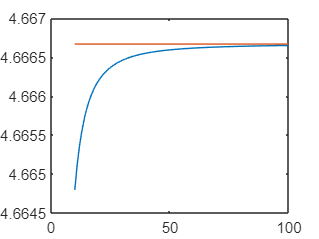

clc;
clear;
close all;

left = 10;
right = 100;
a = 0;
b = 3;

sums = [];
errors = [];

for n = left:right
    delta_x = (b-a)/n;
    xil = linspace(a, b-delta_x, n);
    xir = xil + delta_x;
    left_val = sqrt(xil+1);
    right_val = sqrt(xir+1);
    average = (left_val + right_val)/2;
    trap_sum = sum(average*delta_x);
    sums(n-(left-1)) = trap_sum;
    errors(n-(left-1)) = abs(trap_sum - 14/3);
end

x = left:right;

actual = ones(1, right-left+1) .* 14/3;
plot(x, sums, LineStyle="--");
hold on;
plot(x, actual);